# TEST SULLA RIPETIBILITA' DEL ROBOT

La ripetibilità è una misura della capacità del dispositivo di posizionare il laser nello stesso punto quando viene comandato ripetutamente con gli stessi input. L'approccio specifico utilizzato è:

**Ripetibilità unidirezionale**:

- Si valuta quanto il dispositivo può riprodurre lo stesso movimento in maniera consistente, considerando che lo stesso input dovrebbe produrre la stessa uscita.

- Misuriamo la ripetibilità unidirezionale utilizzando una serie di punti target.

- **    Metodo**:

-         Vengono scelti **25 punti** nello spazio di lavoro del laser.

-         Ogni punto è raggiunto **10 volte** partendo sempre dalla stessa direzione.

- **    Dati raccolti**:

-         Per ciascun punto, si misura la deviazione massima dalla posizione target.

**Metriche utilizzate**:

- La dispersione attorno al punto medio viene calcolata come la ripetibilità unidirezionale R = 2σ, che rappresenta il doppio della deviazione standard RADIALE delle posizioni misurate. 2σr rappresenta il raggio del cerchio che copre circa il 95% dei punti ( Questo indica che con una confidenza del 95%, i movimenti ripetuti cadono entro un certo raggio attorno alla traiettoria media)

clear all

load("C:\Users\mdilucchio\OneDrive - Fondazione Istituto Italiano Tecnologia\Desktop\CALM\Materiale\PROGETTO CALM\Caratterizzazione CALM\Calibration_steps\pixels_to_world_coordinates\improvement_test\dark_720x576\test_accuratezza_robot\ripetibilità\laserWorldPoints_filtered.mat");
video.FrameRate = 25;

fps = video.FrameRate;  % Frame rate della telecamera (25)
interval = 1.5;           % Intervallo in secondi
step = (fps * interval);  % Passo di campionamento (step = round(fps * interval));

% Campionamento delle coordinate a intervalli di 5 secondi
sampled_coords = laserWorldPoints_filtered(75:step:end, :);

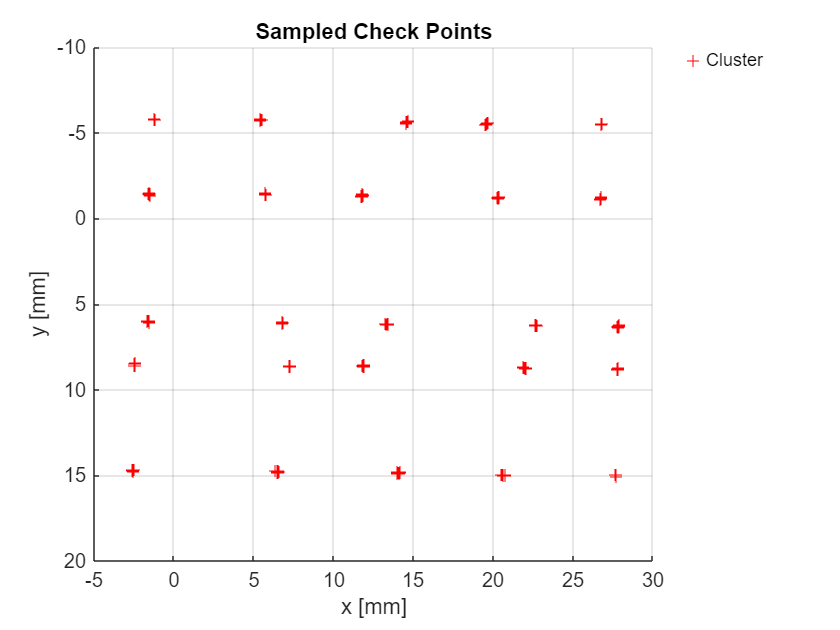

data = sampled_coords(1:240,:); % Prendi i primi 240 punti da sampled_coords che sono quelli che descrivono i 25 cluster da 10 punti ciascuno
% Plot delle coordinate campionate
figure
scatter(data(:,1), data(:,2), "+",'r')
legend('Cluster')
title('Sampled Check Points')
xlabel('x [mm]')
ylabel('y [mm]')
set(gca, 'YDir', 'reverse'); % Invertiamo l'asse Y per riflettere il piano mondo
grid on
box off
legend box off
legend Location bestoutside 

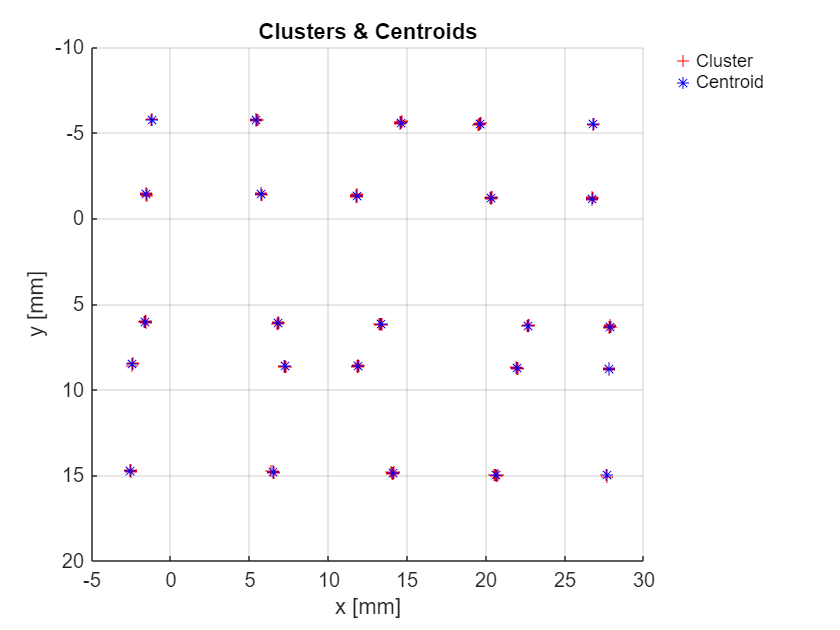

num_points = 25; % Numero totale di cluster
cluster = cell(num_points, 1); % Cell array per contenere i punti di ciascun cluster
cluster_mean = cell(num_points, 1); % Cell array per contenere le medie dei cluster
cluster_std = cell(num_points, 1); % Cell array per contenere le deviazioni standard
dispersion = cell(num_points, 1); % Cell array per contenere la ripetibilità (2σ)
distances = cell(num_points, 1);
results = {}; % Per salvare i dati in formato cell array

step = 48; % costante per determinare la legge di campionamento dei cluster dal cluster N+1 al cluster N-1 

for i = 1:num_points
    
    % parte nuova inizio
    if i == 1 || i == num_points
        % Estrai i punti del gruppo
        cluster{i} = data(i:48:end, :); % Prendi i punti ogni 48-esimo per il primo e utlimo cluster 
    else
        
        indice_iniziale = i; % Primo indice
        salti = [step-2, i+(i-2)]; % Pattern dei salti
        step = step-2;
        % Calcolo gli indici desiderati
        indici = indice_iniziale; % Primo indice
        while indici(end) + salti(mod(length(indici)-1, length(salti))+1) <= length(data)
            indici = [indici, indici(end) + salti(mod(length(indici)-1, length(salti))+1)];
        end

        % Estrai i valori dal vettore
        data_points = [data(indici,1), data(indici,2)];
        cluster{i} = data_points;
    end
    % parte nuova fine

    % Calcola le coordinate della Posizione Media Effettiva (centroide del cluster)
    cluster_mean{i} = [mean(cluster{i}, 1)]; % Media lungo le colonne (dimensione 1)

    % Distanze radiali dal centroide
    % distances = vecnorm(cluster{i} - cluster_mean{i}, 2, 2); % Norme euclidee
    distances{i} = sqrt(sum((cluster{i} - cluster_mean{i}).^2, 2));
    % Calcoliamo la deviazione standard delle distanze radiali dal centroide del cluster (σr)
    cluster_std{i} = std(distances{i});                  % Deviazione standard
    dispersion{i} = (2 * cluster_std{i}) * 1000;      % Ripetibilità a 2σ (espressa in micrometri)

    % Salva i dati locali nel cell array
    results{i, 1} = i; % Numero del cluster
    results{i, 2} = cluster_mean{i}; % Centroide
    results{i, 3} = dispersion{i}; % Ripetibilità locale

end

figure;
hold on

for i = 1:num_points
    scatter(cluster{i}(:, 1), cluster{i}(:, 2), "+",'r'); % Punti del cluster
    plot(cluster_mean{i}(1), cluster_mean{i}(2), 'b*'); % Centro
end
legend('Cluster', 'Centroid')
legend Location bestoutside
legend Box off
title('Clusters & Centroids');
xlabel('x [mm]');
ylabel('y [mm]');
set(gca, 'YDir', 'reverse'); % Riflette il piano mondo
grid on;

hold off;

#### ZOOM PLOT

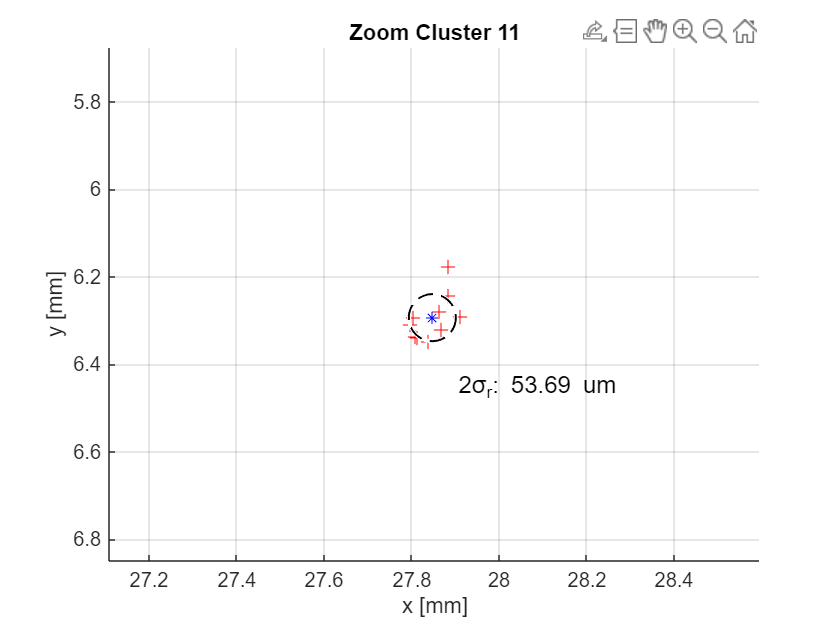

% Seleziona un cluster specifico per lo zoom plot (es. cluster 1)
cluster_id = 11; % Cambia questo valore per selezionare un altro cluster

% Dati del cluster selezionato
selected_cluster = cluster{cluster_id};
centroid = cluster_mean{cluster_id};
selected_dispersion = dispersion{cluster_id};
% Calcola i limiti del cluster
x_min = min(selected_cluster(:, 1));
x_max = max(selected_cluster(:, 1));
y_min = min(selected_cluster(:, 2));
y_max = max(selected_cluster(:, 2));

% Aggiungi un margine ai limiti
margin = 0.5; % Margine in mm
x_lim = [x_min - margin, x_max + margin];
y_lim = [y_min - margin, y_max + margin];

% Zoom plot sul cluster selezionato
figure;
hold on;
scatter(selected_cluster(:, 1), selected_cluster(:, 2), 50, "+", 'r'); % Punti del cluster
scatter(centroid(1), centroid(2), "*", 'b'); % Centro del cluster
viscircles(centroid, selected_dispersion/1000, 'LineStyle', '--','LineWidth', 1,'Color','k'); % Cerchio di ripetibilità (2σ)

%Imposta il range di zoom per includere tutti i punti
xlim(x_lim);
ylim(y_lim);

% % Etichetta la ripetibilità
text(centroid(1) + (selected_dispersion/1000) * 1, centroid(2) + 3*(selected_dispersion/1000), ...
    sprintf('2σ_r: %.2f um', selected_dispersion), 'Color', 'black', 'FontSize', 12);

title(sprintf('Zoom Cluster %d', cluster_id));
xlabel('x [mm]');
ylabel('y [mm]');
set(gca, 'YDir', 'reverse'); % Riflette il piano mondo
grid on;
axis equal;

### Ripetibilità Globale come Media con Incertezza

- **Unione dei Dati Globali**: Combina le distanze radiali di tutti i cluster in un unico dataset globale.

- **Media e Deviazione Standard Globali**: Calcola la media globale delle distanze radiali (dˉg) e la deviazione standard globale (σg).

- **Errore Standard della Media (SEM)**: 

                L'incertezza della media è data da: SEM = σg/sqrt(N)  dove N è il numero totale di punti.

- **Espressione della Ripetibilità Globale**: La ripetibilità globale può essere espressa come: **Ripetibilitaˋ Globale = dˉg ± k⋅SEM** Con k=1 per il 68% di confidenza, k=2 per il 95%, ecc.

% Numero totale di clusters
numClusters = length(cluster);
global_distances = []; % Per calcolare la ripetibilità globale

for i = 1:numClusters
    global_distances = [global_distances; distances{i}];
end

% Calcolo globale
N = length(global_distances); % Numero totale di punti
mean_distance_global = mean(global_distances); % Media globale delle distanze radiali
sigma_global = std(global_distances); % Deviazione standard globale
SEM_global = sigma_global / sqrt(N); % Errore standard della media

% Intervallo di confidenza (95%, k=2)
confidence_interval = 2 * SEM_global;

% Risultati
disp('Ripetibilità Globale come Media con Incertezza:');

Ripetibilità Globale come Media con Incertezza:


disp(['  Media delle distanze radiali: ', num2str(mean_distance_global*1000), ' um']); % Rappresenta una stima sintetica della ripetibilità globale

  Media delle distanze radiali: 51.7461 um


disp(['  Errore standard della media (SEM): ', num2str(SEM_global*1000), ' um']); % Quantifica l'incertezza nella media calcolata

  Errore standard della media (SEM): 1.6495 um


disp(['  Intervallo di confidenza (95%): ±', num2str(confidence_interval*1000), ' um']); %  rappresenta il range entro cui è probabile che si trovi la media effettiva, con una confidenza del 95%

  Intervallo di confidenza (95%): ±3.2991 um


% Stampa completa della ripetibilità globale come media con incertezza
disp(['Ripetibilità Globale (Media ± Incertezza, 95% confidenza): ', ...
      num2str(mean_distance_global*1000), ' ± ', num2str(confidence_interval*1000), ' um']);

Ripetibilità Globale (Media ± Incertezza, 95% confidenza): 51.7461 ± 3.2991 um


% Salva i risultati in un file CSV
custom_folder = 'C:\Users\mdilucchio\OneDrive - Fondazione Istituto Italiano Tecnologia\Desktop\CALM\Materiale\PROGETTO CALM\Caratterizzazione CALM\Calibration_steps\pixels_to_world_coordinates\improvement_test\dark_720x576\test_accuratezza_robot\ripetibilità';
filename = fullfile(custom_folder, 'risultati.csv');
headers = {'Cluster'; 'Centroide (x,y) [mm]'; 'Dispersione (2σ) [um]'};
data_table = cell2table(results, 'VariableNames', headers);
writetable(data_table, filename);

% disp(['Risultati salvati in: ', filename]);